# SAM data analysis

This approach works top-down. 

## Folder content

This assumes all `csv` files in the specified folder contain our data. Notice I use the fullfile path to create the path to avoid the problem with / and \ on different operating systems. 

files = 15625×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file1 = struct with fields:
       name: 'X001Y001.csv'
     folder: '/Users/szymon/Simulations/SAM-analysis/data'
       date: '17-Oct-2018 10:46:01'
      bytes: 2056
      isdir: 0
    datenum: 7.3735e+05


surface = 588

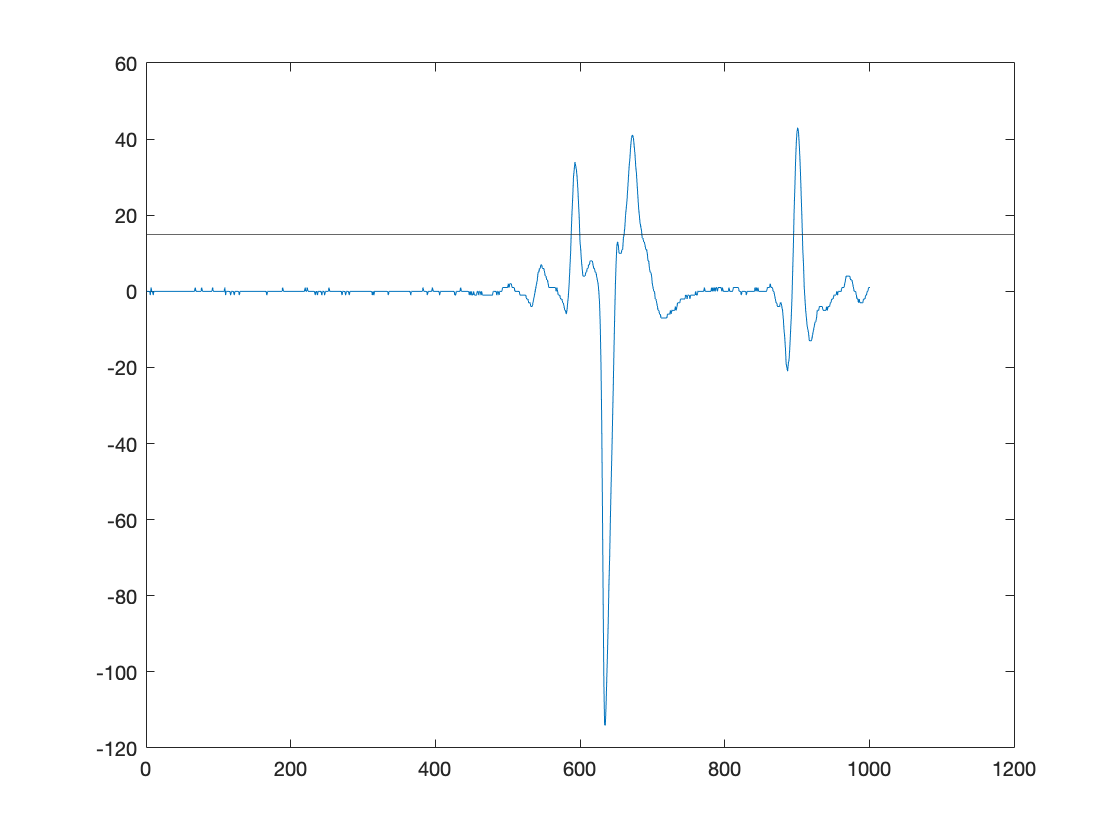

x = 1

y = 1

folder = "data";

## Analysing all the data

This approach assume you have a knowledge of the size of the final image. 

xsize = 125;
ysize = 125;

It is a good practice to put all the parameters explicitly in a variable. This way you create documentation by writing code. 

threshold = 15;

We can now loop over all the files. 

z = [];
for x = 1:xsize
  for y = 1:ysize
    fname = ['X' num2str(x,'%03d') 'Y' num2str(x,'%03d') '.csv'];
    fpath = fullfile(folder, fname);
    data = readmatrix(fpath);
    surface = find(data>threshold, 1);
    if isempty(surface)
      surface = NaN;
    end
    z(x,y) = surface;
  end
end

Now we need to plot the array.

imagesc(z)